# Actividad 3. Freno sobre una barra conductora

**Alejandro Benítez Bravo A01712835**

**Diego Alberto Pasaye González A01708525**

**Darío Alejandro Uribe Hernández A01713776**

**José Miguel Ramírez Gutierrez A01712628**

**Víctor Yael Méndez Alcántara A01368475**

Desarrollamos esta simulación para discutir y sacar conclusiones sobre el frenado magnético de una barra. La idea principal fue observar cómo, debido al movimiento de la barra dentro de un campo magnético, se induce una corriente eléctrica que genera una fuerza de frenado.

Primero, se definió el espacio tridimensional donde se colocó un cuadrado de corriente fija que simula un imán. A través del uso de `meshgrid`, se construyó un plano 2D embebido en 3D, y se calculó el campo magnético resultante usando la ley de Biot-Savart. Se usaron 20 divisiones por eje para visualizar el campo con vectores tridimensionales, graficados con `quiver3`.

Después, se pasó a simular la dinámica de una barra conductora que se mueve en el plano `z = -0.5`. Debido al movimiento de la barra en presencia del campo magnético, se induce una corriente por la Ley de Faraday, la cual se opone al movimiento original por la Ley de Lenz. Esta corriente se calculó en cada instante con base en la interpolación del campo `Bz` a lo largo de la barra. A partir de la corriente inducida, se obtuvo la fuerza de frenado usando la fórmula `F = I × B`.

La evolución temporal de la barra se resolvió usando el método de Euler, Se detuvo la simulación automáticamente cuando la barra salió del área definida o su velocidad fue prácticamente cero.

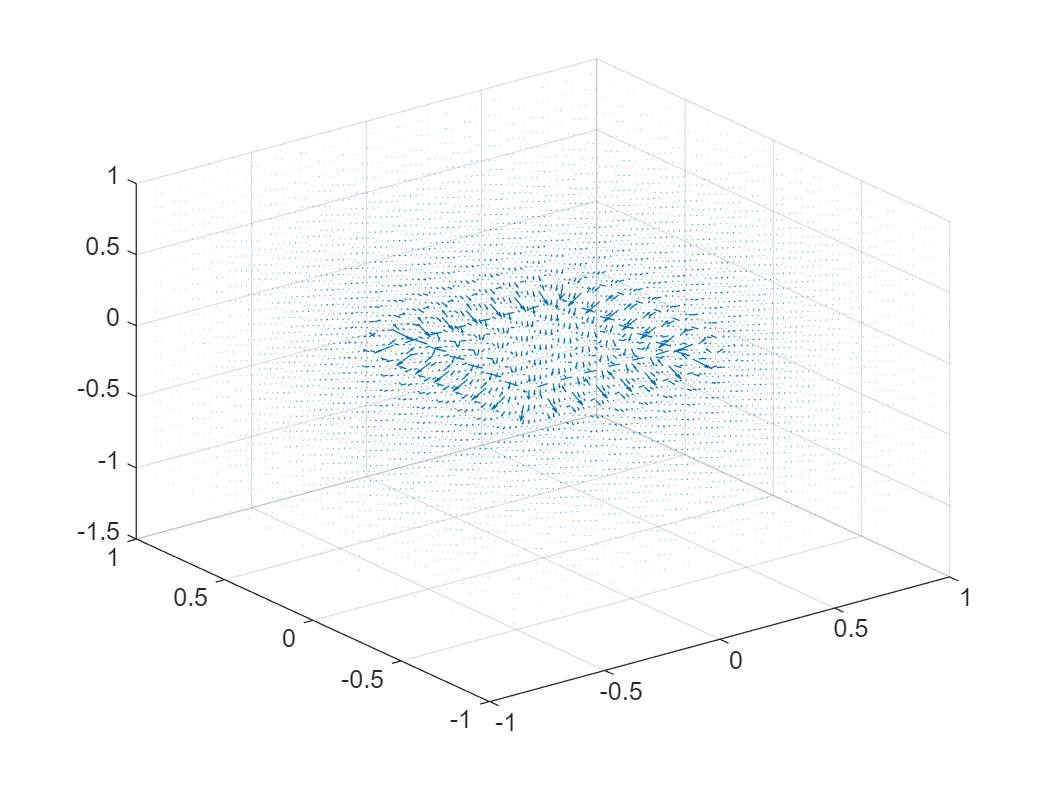

clear all, close all

m0 = 4*pi*1e-7;
x = linspace(-1, 1, 20);
y = linspace(-1, 1, 20);
z = linspace(-1, 1, 20);
[X,Y,Z] = meshgrid(x,y,z);

sideLength = 0.8;
I = 5;

wires = [
    -sideLength/2, -sideLength/2, 0,  sideLength/2, -sideLength/2, 0;
     sideLength/2, -sideLength/2, 0,  sideLength/2,  sideLength/2, 0;
     sideLength/2,  sideLength/2, 0, -sideLength/2,  sideLength/2, 0;
    -sideLength/2,  sideLength/2, 0, -sideLength/2, -sideLength/2, 0
];

Bx = zeros(size(X));
By = zeros(size(Y));
Bz = zeros(size(Z));

for i = 1:numel(X)
    BTotal = [0, 0, 0];
    for w = 1:size(wires, 1)
        lvinit = wires(w, 1:3);
        lvend = wires(w, 4:6);
        a = lvinit - lvend;
        b = lvinit - [X(i), Y(i), Z(i)];
        c = lvend - [X(i), Y(i), Z(i)];
        cca = cross(a,b);
        if norm(cca) < 1e-10
            B = [0, 0, 0];
        else
            B = (m0*I/(4*pi)) * (cca/norm(cca)^2) * (dot(a,c)/norm(c) - dot(a,b)/norm(b));
        end
        B(isnan(B)) = 0;
        B(isinf(B)) = 0;
        BTotal = BTotal + B;
    end
    Bx(i) = BTotal(1);
    By(i) = BTotal(2);
    Bz(i) = BTotal(3);
end

quiver3(X,Y,Z,Bx,By,Bz)

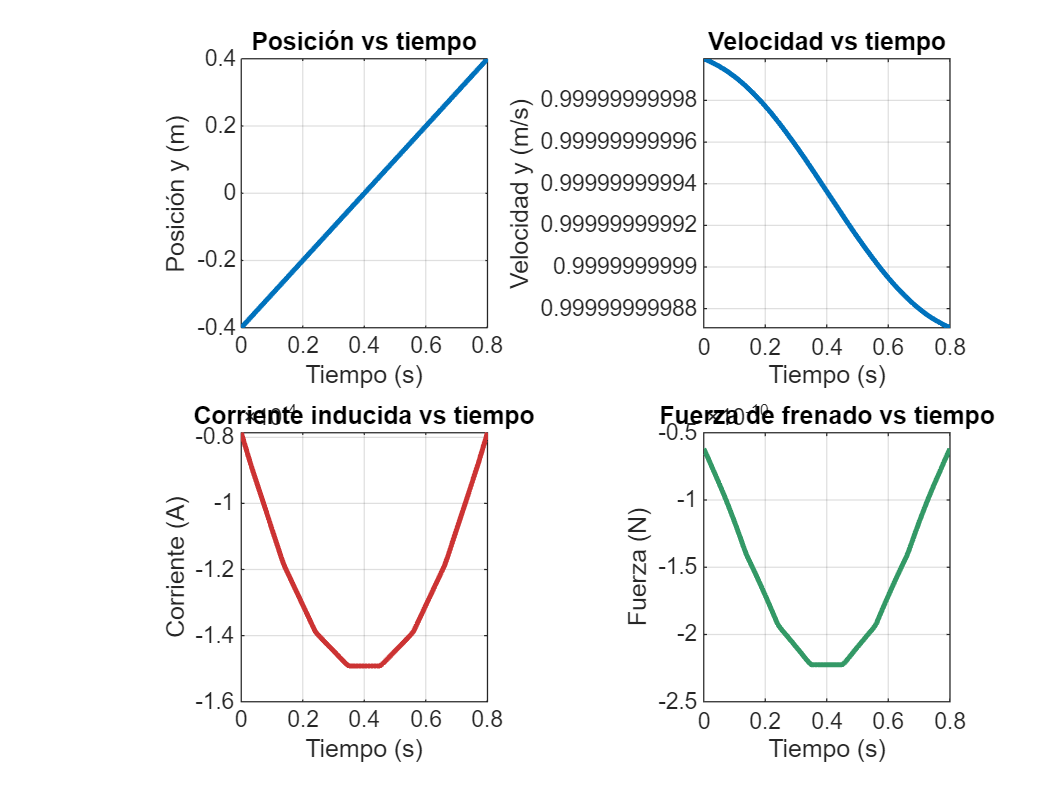


n = 1000; 
t0 = 0;
tf = 10;
t = linspace(t0, tf, n);
dt = (tf - t0) / n;
m = 1; 
R = 0.01; 

nPoints = 20;
xBar = linspace(-sideLength/2, sideLength/2, nPoints);

[~, zIdx] = min(abs(z - (-0.5)));
BzPlane = Bz(:,:,zIdx);

yb = [];
vby = [];
I = []; 
Fy = [];
timePoints = [];

currentY = -sideLength/2;
currentVy = 1; 
stopSimulation = false;

for i = 1:n
    BzInterp = interp2(X(:,:,zIdx), Y(:,:,zIdx), BzPlane, xBar, currentY*ones(size(xBar)));
    
    currentI = (currentVy/R) * trapz(xBar, BzInterp);
    
    currentFy = trapz(xBar, -currentI * BzInterp);
    
    if ~stopSimulation
        yb(end+1) = currentY;
        vby(end+1) = currentVy;
        I(end+1) = currentI;
        Fy(end+1) = currentFy;
        timePoints(end+1) = t(i);
    end
    
    currentVy = currentVy + (currentFy/m) * dt;
    currentY = currentY + currentVy * dt;
    
    if abs(currentY) > sideLength/2 || abs(currentVy) < 1e-6
        stopSimulation = true;
    end
    
    if stopSimulation && i > 1
        break;
    end
end

t = timePoints;

figure;

subplot(2,2,1);
plot(t, yb, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Posición y (m)');
title('Posición vs tiempo');
grid on;
xlim([t(1) t(end)]);

subplot(2,2,2);
plot(t, vby, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Velocidad y (m/s)');
title('Velocidad vs tiempo');
grid on;
xlim([t(1) t(end)]);

subplot(2,2,3);
plot(t, I, 'LineWidth', 2, 'Color', [0.8 0.2 0.2]);
xlabel('Tiempo (s)');
ylabel('Corriente (A)');
title('Corriente inducida vs tiempo');
grid on;
xlim([t(1) t(end)]);

subplot(2,2,4);
plot(t, Fy, 'LineWidth', 2, 'Color', [0.2 0.6 0.4]);
xlabel('Tiempo (s)');
ylabel('Fuerza (N)');
title('Fuerza de frenado vs tiempo');
grid on;
xlim([t(1) t(end)]);

Las gráficas muestran claramente cómo la velocidad de la barra disminuye con el tiempo, lo que indica el efecto del freno magnético. Además, se observa cómo la corriente inducida y la fuerza de frenado caen también con el tiempo, lo cual concuerda con el hecho de que estas dependen directamente del movimiento de la barra.

Al desplazarse, la barra experimenta un cambio en el flujo magnético, lo que induce una corriente eléctrica (Ley de Faraday). Esta corriente alcanza un valor negativo máximo a la mitad del trayecto y luego disminuye, indicando que el sistema responde al cambio de flujo. La fuerza de frenado generada por esta corriente (según la Ley de Lorentz) tiene una forma similar, oponiéndose al movimiento de la barra.

Como resultado, la velocidad de la barra disminuye ligeramente con el tiempo, aunque no es muy notorio, mientras que la posición sigue aumentando pero con una pendiente cada vez menor.